# Notes regarding lab format

We will use Matlab Livescript for this lab. Livescript allows switching between text and code cells. 

You will find the entire lab manual in this file. Some exercises require you to write a text answer, others require you to write code. You should not define functions inside this file. Instead save functions to the functions folder and call them from the code cells in this notebook.

Your finished lab report should be a .zip-file containing the data folder, your functions folder and this livescript file. As usual, you should also provide a pdf of the result of running the live script (in the Live Editor, you can **export to pdf** under Save) where all result images should be visible.

In certain sections of this lab, MATLAB might throw warnings about conditioning of matrices. You should turn them off using the command  `warning('off','all')` and submit the final pdf withput these warnings displayed. 

Since we need to access the functions and data folder the first step is to add these two locations MATLAB's path.

addpath('./functions');
addpath('./data');

# Lab 3: Image Registration

An affine transformation is written as:


$$\left(\begin{array}{l}
\tilde{x} \\
\tilde{y}
\end{array}\right)=\left(\begin{array}{ll}
a & b \\
c & d
\end{array}\right)\left(\begin{array}{l}
x \\
y
\end{array}\right)+\left(\begin{array}{l}
t_{x} \\
t_{y}
\end{array}\right)=A\left(\begin{array}{l}
x \\
y
\end{array}\right)+t$$


Apart from rotation, translation and scaling, it also allows stretching the image in an arbitrary dimension. 

## Ex 3.1 Getting started

Any matrix $A$ can be written as $A=U\Sigma V^T$, a so-called Singular Value Decomposition, where $U,V$are orthogonal matrices and $\Sigma =\left\lbrack \begin{array}{cc}
\lambda_1  & 0\\
0 & \lambda_2 
\end{array}\right\rbrack$is a diagonal matrix with $\lambda_1,\lambda_2$ non-negative. Using this decomposition, describe what an affine transformation actually does when applied to an image. If one would like to stretch the image along the x-axis, one simply applies A=diag([k,1]) for some stretching factor k. How should one obtain a stretching with a factor k along the diagonal direction of an image with an affine transformation? Note, A=diag([k,k]) would give a uniform stretching of the image.

**Your answer here with explanation as a comment here.	**

%% Considering SVD, an affine transformation can be thought of as a combination 
% of a rotation, a scaling, and a rotation back to the original coordinate system.
% The rotation is given by the matrix V, the scaling is given by the diagonal 
% matrix Σ, and the final rotation back to the original coordinate system is 
% given by the matrix U^T.

% First, Compute the Singular Value Decomposition (SVD) of the image
% matrix; Construct the scaling matrix Σ' as follows: Σ' = [k, 0; 0, 1]. Scale
% the image along the diagonal direction by a factor of k, while leaving the 
% other direction unchanged. A' as follows: A' = U * Σ' * V^T. Apply A to
% the image to get the new diagonal strechting image.

## Ex 3.2 Minimum correspondences

What is the minimal number of point correspondences, K, required in order to estimate an affine transformation between two images?

**Your answer here with explanation as a comment here.	**	

%%At least three non-collinear points in each image. In above equation, 6
%%unknowns: a, b, c, d, t_x, t_y. Need 6 equations to solve, so at least 
%%three points in each image. These 6 unknowns can also be considered as 6
%%freedoms(three for translation, two for scaling, and one for rotation).

In general, an estimation problem where the minimal of amount of data is used to estimate the unknown parameters is called **a minimal problem**.

Once you have found a proper coordinate transformation between two images, you can use the provided function affine_warp to warp the source image and create a warped image. Let’s try it. 

## Ex 3.3 Trying warping

Load the image mona.png to the variable img. Try running the following code snippet :

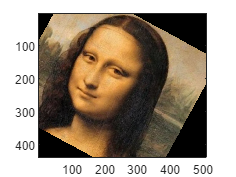

img = imread('data/mona.png'); 
A = [0.88 -0.48; 0.48 0.88];
t = [100;-100];
target_size = size(img);
warped = affine_warp(target_size, img, A, t); imagesc(warped);
axis image;			

Change the values in A and t to see what happens. First, swap A for eye(2,2) to try a pure translation and plot the result. Then, swap A and t for a stretching along a diagonal as in Ex 3.1 but without rotating and translating the image. Plot the result.

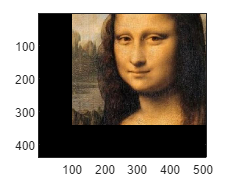

A = eye(2,2);
t = [100;-100];
target_size = size(img);
warped = affine_warp(target_size, img, A, t); imagesc(warped);
axis image;	

a = pi/4;
k = 2;
U = [cos(a), -sin(a); sin(a), cos(a)];
V = [cos(a), sin(a); -sin(a), cos(a)];
Sigma = diag([k,1]);
A = U*Sigma*V

A =     1.5000    0.5000
    0.5000    1.5000


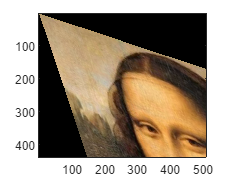

t = [0;0];% no translation
target_size = size(img);
warped = affine_warp(target_size, img, A, t); imagesc(warped);
axis image;

Explain what you observe in the two cases. **Write your answer as a comment here.**

%%First case: eye generates identity matrix, which means pure translation.
%%As we can see in the graph, the picture translate a bit to the upper
%%right corner.
%%Second case: no translation. Diagonal value in matrix A exists
%%while other elements are 0, which means only streching along a diagonal
%%direction. A scales the image along the x-axis by a factor of "k" and 
%% along the y-axis by a factor of "k".

## Ex 3.4 Writing test case				

For any estimation task it is a good idea to have at least one test case where you know what the answer should be. In this exercise you should make such a test case for RANSAC. Start by generating random points, `pts`, and a random transformation. Then transform these points to create a `pts_tilde`. If you want to make it more realistic, add random noise to the points. You now have two sets of points related by a known affine transformation as in *Ex 3.2*. In the following exercises you will try to estimate this transformation. As you know the correct answer it is easy to detect if you make a mistake. 					

**Make a function** 

that generates a test case for estimating an affine transformation. The transformation should map `pts` to `pts_tilde.` Don't add any outliers now. Outputs `pts` and `pts_tilde` should be `2 x N-arrays`. Also output the *true* transformation, so you know what to expect from your code.

After you have written the function, test it with a few runs here :

[pts, pts_tilde, A_true, t_true] = affine_test_case()

pts =    -1.3548    0.5620    0.3637    0.5555    1.0477    0.9936    0.0979    0.5979    0.4298    1.4037
   -1.0795    0.7439   -0.0707   -0.0222    0.8629   -0.9694   -0.8437    1.1421   -0.0332   -0.1588


pts_tilde =     3.0504    5.8976    5.4152    5.6600    6.5161    5.9015    4.8644    6.0601    5.5058    6.6368
   -3.7281   -2.4610   -3.0930   -3.0733   -2.4144   -3.8749   -3.6848   -2.1461   -3.0696   -3.2674


A_true =     1.2000    0.3000
   -0.1000    0.8000


t_true =      5
    -3


## Ex 3.5 Writing a minimal solver

Make a minimal solver for the case of affine transformation estimation. In other words, **make a function**

that estimates an affine transformation mapping `pts` to `pts_tilde`, where `pts` and `pts_tilde` are `2 x K - arrays` and `K` is the number you found in *Ex 3.2*. Try your function on points from the test case in *Ex 3.4*.

[A, t] = estimate_affine(pts, pts_tilde)

A =     1.2000    0.3000
   -0.1000    0.8000


t =     5.0000
   -3.0000


## Ex 3.6 Computing residuals

Make a function

that computes the lengths of 2D residual vectors. The function should return an array with N values. *Hint : *Given a `2 x N` matrix, stored in `M`, the column-wise sum of the **squared** elements can be computed as `sum(M.^2, 1)`.

**Verify** that for no outliers and no noise, you get zero residual lengths given the true transformation:

res = residual_lgths(A, t, pts, pts_tilde)%res=10E-29

res = 1.0e-28 *

    0.2564    0.0079    0.0394    0.0099    0.0079    0.0020    0.0631    0.0316    0.0158    0.0020


sum(res)

ans = 4.3585e-29

## **Ex 3.7 Test case with outliers**

Modify your function `affine_test_case `to create a new function `affine_test_case_outlier `that takes a parameter `outlier_rate` and produces a fraction of outliers among the output points. For example, if `outlier_rate` is 0.2, then 80% of the samples will be related by `pts_tilde = A_true * pts + t_true`. While for the remaining 20%, pts_tilde can be distributed uniformly within some range. 

**Test your code here:**

outlier_rate = 0.2

outlier_rate = 0.2000

[pts, pts_tilde, A_true, t_true] = affine_test_case_outlier(outlier_rate)

pts =     0.4117    1.3719    1.1175    0.0039   -0.2761    0.5285   -0.0769   -0.0043   -1.1917   -0.2088   -1.0638    1.3529    0.3727   -0.8332    1.2622   -0.2539   -0.0932    0.6787   -1.8267   -0.5319
    0.6164   -0.0531   -0.1441    0.3537    1.1076   -0.4023   -0.5069    0.5285    0.1203   -1.0691    0.9766   -0.9338   -0.4713   -0.5214   -1.2946    1.0764    0.7967    1.9351   -0.7913    2.2436


pts_tilde =    -0.3798   -0.8149    6.2977    0.1418    5.0009    5.5135    4.7556    5.1534    3.6060    4.4287    4.0164    6.3434    5.3058    3.8438    6.1263    5.0182    5.1272    6.3950    0.9761    5.0348
    0.5329   -0.1671   -3.2270   -0.1268   -2.0863   -3.3747   -3.3978   -2.5768   -2.7846   -3.8344   -2.1123   -3.8823   -3.4143   -3.3338   -4.1619   -2.1135   -2.3533   -1.5198    0.9221   -1.1520


A_true =     1.2000    0.3000
   -0.1000    0.8000


t_true =      5
    -3


## **Ex 3.8 Writing a RANSAC based solver**

Make a function					

that uses RANSAC to find an affine transformation between two sets of points. (Like before the transformation should map `pts` to `pts_tilde`.) Test your function on test cases generated with your function `affine_test_case_outlier`. 

**RANSAC Note** : You can use the notes to decide on the number of RANSAC iterations needed given your required confidence and estimated inlier ratio. You can also use fixed iterations but make sure that you have enough iterations to find a reasonable solution.

**Verify your code here**. Try different outlier rates. Make sure that you get the right transformation for a reasonable outlier rate as well. 

threshold = 0.000001;
outlier_rate = 0.4%

outlier_rate = 0.4000

[pts, pts_tilde, A_true, t_true] = affine_test_case_outlier(outlier_rate)

pts =    -1.2922   -1.9271   -1.1508   -0.4075    1.9994   -0.0311   -0.4202    0.8346   -0.1038    0.3678   -0.0259    0.0737   -0.2259   -0.5465    0.8750   -0.1969   -0.5606   -0.5244    1.1248   -0.6913
    0.6875    1.3766   -1.0413   -1.1614    0.6946   -0.3015    2.5121   -0.2210    0.3011    1.8875    1.1634    2.0084    0.1760   -0.6430   -0.5686   -1.0336    2.1221    1.0361    0.0525    0.0815


pts_tilde =     3.6556   -1.3360   -1.3792    0.2071    7.6076    4.8722   -0.8421    5.9352    4.9657    6.0076    5.3180   -0.3852    0.6050    4.1512    5.8794    1.6185    4.9639    0.5398    6.3656    4.1949
   -2.3208    2.1086    0.7963    0.1693   -2.6443   -3.2381   -0.2989   -3.2602   -2.7488   -1.5268   -2.0667   -1.7466    0.6251   -3.4598   -3.5424    1.6879   -1.2462   -0.4576   -3.0705   -2.8657


A_true =     1.2000    0.3000
   -0.1000    0.8000


t_true =      5
    -3


[A_withoutRANSAC,t_withoutRANSAC] = estimate_affine(pts, pts_tilde)

A_withoutRANSAC =     2.2497   -0.0413
   -1.0998    0.0274


t_withoutRANSAC =     3.4843
   -1.6234



[A,t] = ransac_fit_affine(pts, pts_tilde, threshold)

A =     1.2000    0.3000
   -0.1000    0.8000


t =     5.0000
   -3.0000


## Ex 3.9 Aligning images

For this exercise, you should use the function

in a similar way as in *Lab 1* to extract SIFT features. Note that it only works for grayscale images, so if you have a colour image you need to convert it to grayscale before with `rgb2gray`. To match features you can use the built-in function matchFeatures. To use the Lowe criterion (with threshold 0.8) you should use the following options: 

**Write a function:**

            warped = align_images(source, target, thresh) 

that uses SIFT and RANSAC to align the `source` image to the `target` image with `thresh` as the residual threshold for counting inliers in your RANSAC. To perform the actual warping, use the `affine_warp` function within your `align_images` function. Be very careful about the order in which you send the points to RANSAC. You can visualize your correspondences with **showMatchedFeatures**.

**Align **`vermeer_source.png` to `vermeer_target.png using` your `align_images` function. Plot the source, target and warped source images together.

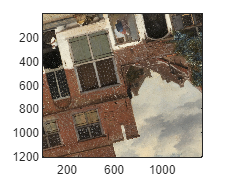

%% Your code here
img_src = imread('vermeer_source.png');
source = rgb2gray(img_src);

img_tgt = imread("vermeer_target.png");
target = rgb2gray(img_tgt);

warped = align_images(source, target, 1);

%% You can use the following code snippet to plot images next to each other. You can also plot them in more appealing ways.
figure
imagesc(img_src);axis image

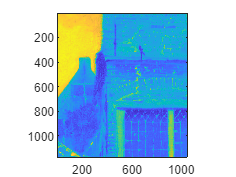

figure
imagesc(warped);axis image

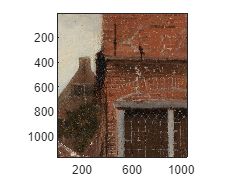

figure
imagesc(img_tgt);axis image

## Ex 3.10 Aligning images with known orientation

Medical images often have less local structure, making SIFT matching more difficult. It often works better if we drop the rotation invariance. The provided feature extraction function has an option for this. 

assumes that the image has a default orientation. Plot the warped and the target images next to each other to verify your result. Modify your `align_images` function to create function `align_images_v2 `so that it also takes a boolean argument, `upright` stating whether the images have the same orientation, i.e. 

Try aligning the images *CT_1.jpg* and *CT_2.jpg*. Try with and without rotation invariance and try different outlier thresholds. If you are still not successful, try the alternative descriptor SURF which is also implemented in MATLAB with

Also plot the warped image and the target image next to each other so one can verify the result (if successful).

source = imread('CT_1.jpg');

target = imread('CT_2.jpg');

threshold = 30;
upright = true;
warped = align_images_v2(source, target, threshold, upright);

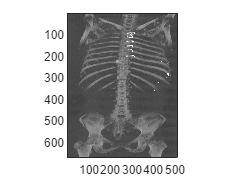


figure
imagesc(warped); axis image; colormap gray

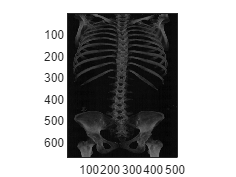

figure
imagesc(target); axis image; colormap gray

**Explain your observations of using and not using rotation invariance at different thresholds here.**

%%if not use rotation invariance and still use SIFT, the threshold must be
%%very large to get an image, and the image looks very tricky; if use
%%roation invariance and still use SIFT, the threshold can be smaller to get a
%%picture while the picture still looks wrong. The final solution is to use
%%SURF descriptor and also rotation invariance. The final threshold is much
%%smaller and seems to get a resonable solution.

## Ex 3.11 Flouroscent image example (optional)

Try aligning *tissue_fluorescent.tif *and *tissue_brightfield.tif*. In the fluorescent image, the intensities are basically inverted, so you need to invert one of the images before computing descriptors. (Otherwise you won’t get any good matches.) You can invert it by taking 

Plot the warped image and the target image side by side so one can verify the result.

threshold = 200;
upright = true;

source = imread('tissue_fluorescent.tif');
im_tgt = imread('tissue_brightfield.tif');

target = rgb2gray(im_tgt);

source = 255 - source;
%%SIFT to get resonable result
warped = align_images_v2(source,target,threshold,upright);

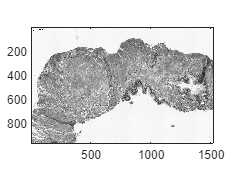


imagesc(target), axis image

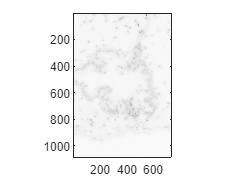

imagesc(source), axis image

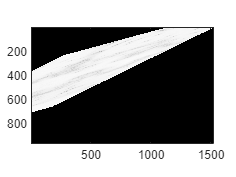

imagesc(warped), axis image

Note that this example is optional due to the fact it may be hard to get good correspondences with MATLAB's implementation of SIFT.

# Warping

## Ex 3.12 Get pixel value

So far you have used Matlab's function for warping. The reason is that it is difficult to write a Matlab function for warping that is not painfully slow. Now you will get to write one anyway, but we will only use it for very small images. 

**Write a function**

that gives you the pixel value at `position`. If the elements of `position` are not integers, select the value at the closest pixel. If it is outside the image, return 1 (=white). Try your function on a simple image to make sure it works. 

img = im2gray(imread('source_16x16.tif'));
sample_image_at(img, [1, 1])

ans = uint8
255

sample_image_at(img, [100, 20000])

ans = 1

sample_image_at(img, [90000, 0])

ans = 1

## Ex 3.13 Warp

Now, you will do a warping function that warps a `16 x 16` image according to the coordinate transfomation provided in `transform_coordinates.m`. 

Write a function 

that warps source according to `transform_coordinates` and forms an output `16 X 16` image warped. Use your function `sample_image_at` to extract pixel values. Try the function on `source_16x16.tif` and plot the answer using imagesc. You will get to see a meaningful image if you get it right.

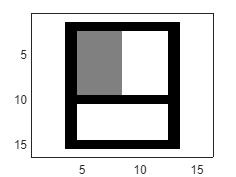

source = imread('source_16x16.tif');
imagesc(source)

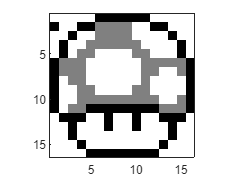

warped = warp_16x16(source);
imagesc(warped), axis image

# Least Squares

## Ex 3.14 LS

Write a function

that estimates an affine transformation mapping `pts` to `pts_tilde `in least squares sense, i.e., all points in `pts` and `pts_tilde` are used to compute the transformation. (Depending on how you wrote you estimate_affine.m, this might be very easy.) Use it on the inliers from RANSAC to refine the estimate. Add this to `align_images `to form a new function` align_images_inlier_ls` and test it on the `Vermeer` images for different outlier thresholds. Plot the final result images next to each other.

sres1 = single
2.4377e+05

sres2 = single
2.4456e+05

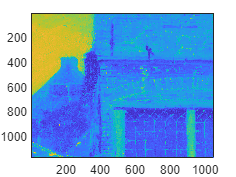

sres1 = single
2.4618e+05

sres2 = single
2.4321e+05

sres1 = single
2.4311e+05

sres2 = single
2.4554e+05

sres1 = single
2.4317e+05

sres2 = single
2.4702e+05

sres1 = single
2.4243e+05

sres2 = single
2.4413e+05

source = rgb2gray(imread('vermeer_source.png'));
target = rgb2gray(imread('vermeer_target.png'));

for threshold = [1,5,10,20,50]

    warped= align_images_inlier_ls(source, target, threshold, false);

    figure, imagesc(warped),imagesc(source),imagesc(target);

end

Do you notice an improvement? Observe visually and also in terms of the residuals. **Explain your observations and the plausible reasons behind them as comment here.**

% Since my first estimate_affine function already used least square method,
% there won't be much differencen considering both visual sense and
% residuals. 
% However,
% There are different methods for computing affine transformation. For example,
% another method is Direct Linear transformation(DLT), In terms of the residuals, 
% the least squares method will generally provide a better fit than the DLT method. 
% This is because the least squares method minimizes the sum of squared distances 
% between the transformed points and the target points, while the DLT method only 
% enforces the constraints between the corresponding points in homogeneous coordinates.
% Thus, LSM will generally provide a better approximation of the true transformation.
